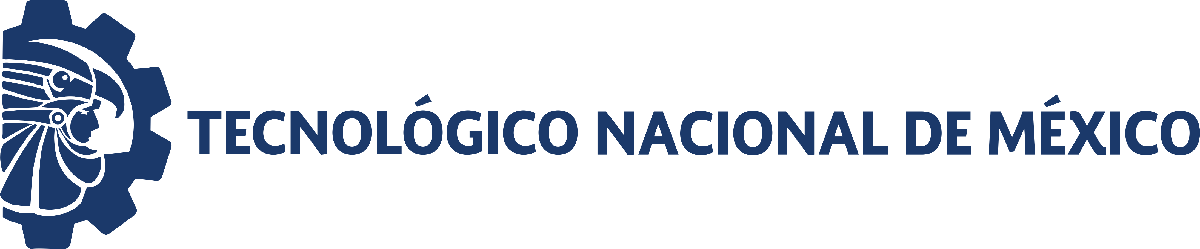                                 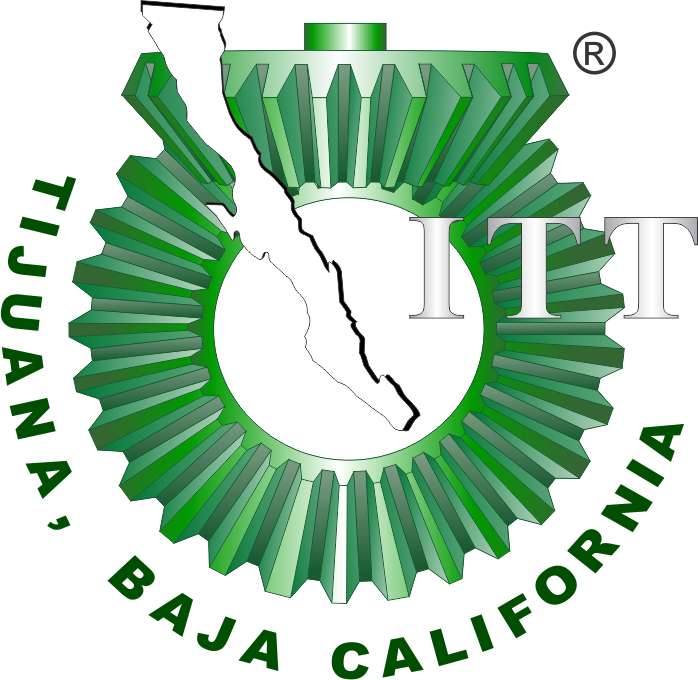

# Práctica 3: Sistema Musculoesqueletico

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

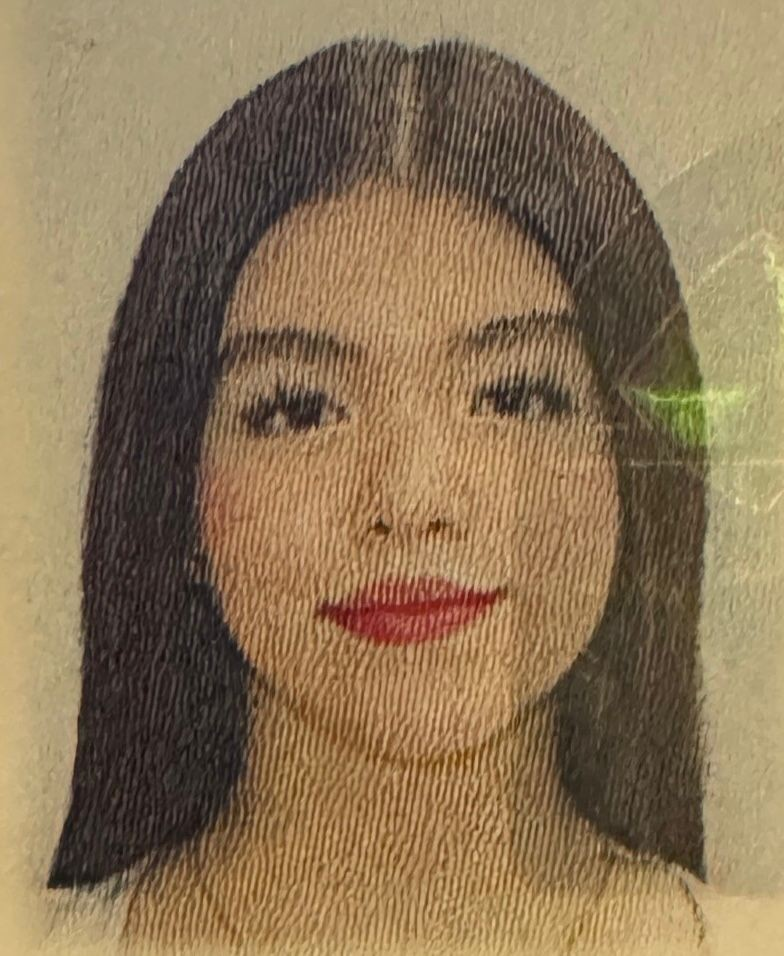

Nombre del alumno: **Angelica Ashia Haro Najar**

Número de control: **23210708**

Correo institucional: **l23210708@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema3';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
x = sim(file, parameters);



## Respuesta del sistema 

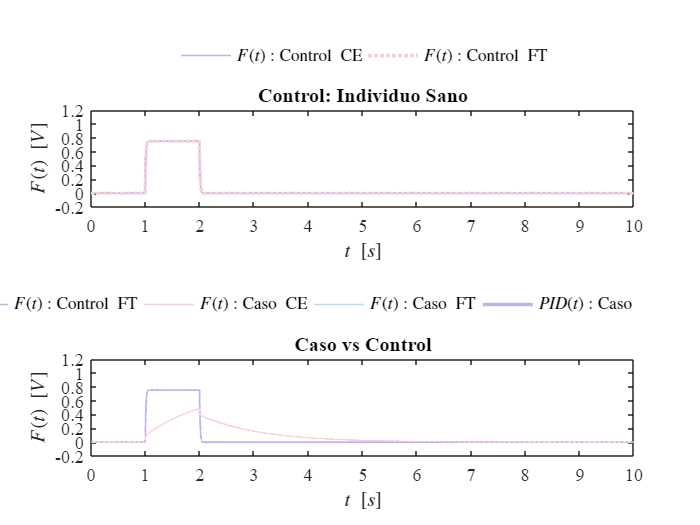

plotsignals(x.t, x.Pp0, x.Pp1, x.Pp2, x.Pp3, x.PID1)

## Función: Respuesta a las señales

function plotsignals(t, Pp0, Pp1, Pp2, Pp3, PID1)

set(figure(), 'Color', 'w')
set(gca, 'Units', 'centimeters', 'Position', [1, 1, 25, 20])

colors = [194, 180, 234;
              249, 207, 221;
              177, 223, 243]/255;
    colororder(colors)

subplot(2,1,1); box on; hold on;
P = plot(t, Pp0, '-', ...
         t, Pp1, ':', ...
         'LineWidth', 1);
set(P(2), 'LineWidth', 2)

L = legend('$F(t): \mathrm{Control\ CE}$', ...
           '$F(t): \mathrm{Control\ FT}$');
set(L, 'Interpreter',  'Latex', ...
       'FontSize',      10, ...
       'Location',      'NorthOutside', ...
       'Box',           'Off', ...
       'Orientation',   'Horizontal');

xlabel('$t\ [s]$',    'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$F(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)

xlim([0, 10]); xticks(0:1:10);
ylim([-0.2, 1.2]); yticks(-0.2:0.2:1.2);

T = title('Control: Individuo Sano'); set(T, 'FontSize', 10);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

subplot(2,1,2); box on; hold on;
P = plot(t, Pp1,  '-', ...
         t, Pp2,  '-', ...
         t, Pp3,  '-', ...
         t, PID1, ':', ...
         'LineWidth', 1);
set(P(4), 'LineWidth', 2)

L = legend('$F(t): \mathrm{Control\ FT}$', ...
           '$F(t): \mathrm{Caso\ CE}$',    ...
           '$F(t): \mathrm{Caso\ FT}$',    ...
           '$PID(t): \mathrm{Caso}$');
set(L, 'Interpreter',  'Latex', ...
       'FontSize',      10, ...
       'Location',      'NorthOutside', ...
       'Box',           'Off', ...
       'Orientation',   'Horizontal');

xlabel('$t\ [s]$',    'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$F(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)

xlim([0, 10]); xticks(0:1:10);
ylim([-0.2, 1.2]); yticks(-0.2:0.2:1.2);

T = title('Caso vs Control'); set(T, 'FontSize', 10);
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

exportgraphics(gcf, fullfile(pwd,'musculoesqueletico.pdf'), 'ContentType', 'vector')
end